# Importance of Water

## Group Members: Yessica Nelson, Daniel Silva, Travis Merrill, and Jason Morales. 

%File: final_project_live
%Group Members:Yessica Nelson, Daniel Silva, Travis Merrill and Jason 
%Morales

## Purpose:

%Purpose: Our purpose is to show that providing clean water is a global 
%issue that needs to be addressed. We are supporting this by presenting data sets 
%that directly present the issue at hand.In addition to showing the
%problem, we are also considering potential solutions to this issue.

%Clearing previous variables 
clc; 
clear all; 
close all;

 


## Daily water use

% Utilize various data sets and display relevant figures that illustrate the major sources of water use
% Water Use Per day Data from 2002 
country=xlsread('Average_Water_Use_Per_Person_Per_Day','a2:a30'); %read data from excel file 
litres=xlsread('Average_Water_Use_Per_Person_Per_Day','c2:c30'); 
[num, txt, raw] = xlsread('Average_Water_Use_Per_Person_Per_Day.xlsx');% created to read txt from excel and use as labels 

% Use excel data to plot a horizontal bar graph 
figure(1) 
fullscreen=get(0,'ScreenSize');% enlarging the figure for better visibility
figure('Position',[0,-50 fullscreen(3),fullscreen(4)])
barh(country,litres) 
Labels=txt;% using countries in excel sheet as labels 
set(gca, 'YTick', 1:30, 'YTickLabel', Labels); % renaming tick labels
axis auto 
xlabel Liters 
title 'Average Water Use per Person per Day';
hold on

# `Average Water User per Person per Day`

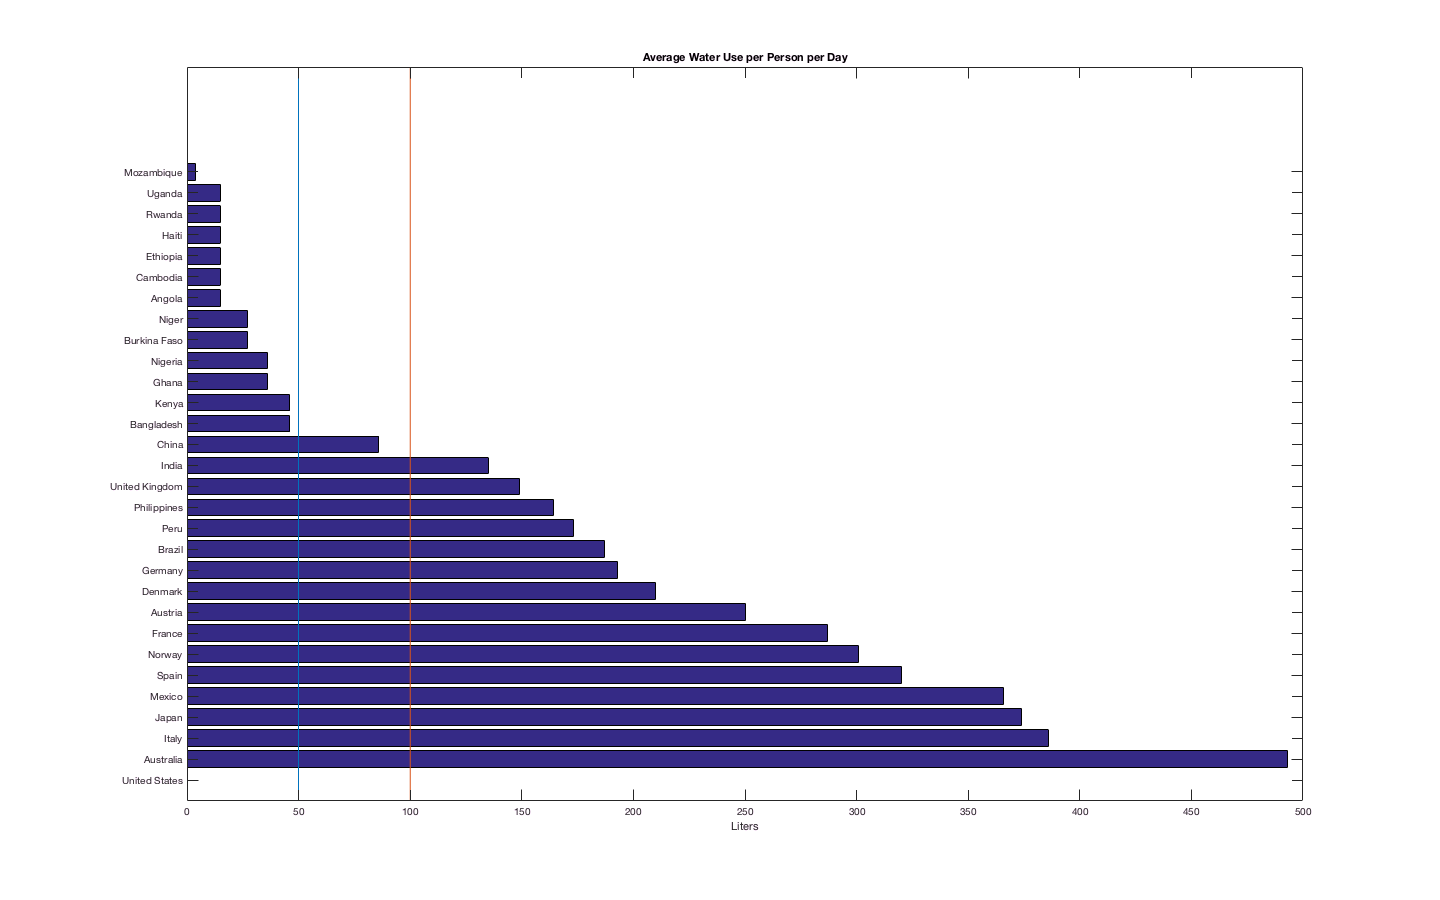

%From UN information setting a range of what avg water usage should be 
%starting at 50L and ending at 100L 
ylim=get(gca,'ylim'); 
hold on 
plot([50 50],ylim) 
plot([100 100],ylim)

- Questions to ask user. Would you like to know specific details on daily water usage?

- if Yes... To proceed, please type in the name of any of the  30 countries  presented:

- if wrong.. Please try another country that is part of the 30 presented on the graph.

- if correct display: The daily water use for ---country typed --- is ---value---.** If below 50 display -- This country is below the UN recomended  daily water usage level . ** If above-- This coutry is__ **liters**_  above the UN recommended water usage level. ** if within levels... This country is within the UN recommended water usage levels. 

- would you like to select a different country?

# `Water availability by Country`

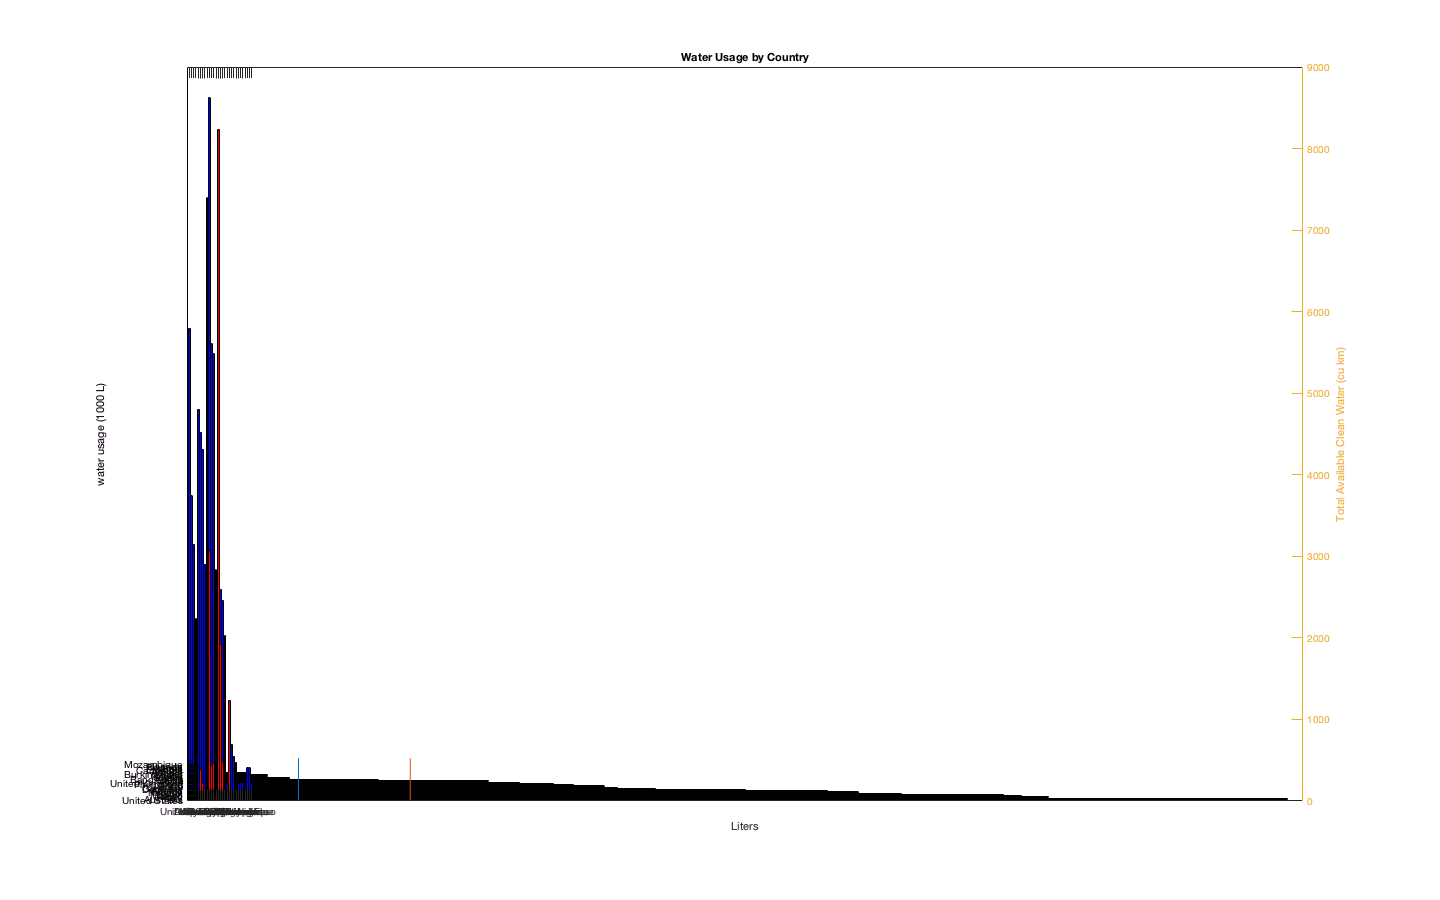

figure(2)
water = xlsread('water_availability_by_country','B2:B30');

x_tick = [1:29];

 

yyaxis right;

bar(water,'stacked','r');

ylabel('Total Available Clean Water (cu km)');

 

 

yyaxis left;

usage = xlsread('water_availability_by_country','C2:C30');

bar(usage,'b','stacked');

ylabel('water usage (1000 L)');

 

[~,txt,~] = xlsread('water_availability_by_country','A2:A30');

country = txt;

xticks(1:29);

set(gca,'xticklabel',country);

title('Water Usage by Country');
hold on;

** have not heard from travis in regards to what questions to prompt user for.

## What sectors use up the most water?

% Figure to demonstrate economic sectors that compete for freshwater resources
figure(3) 
A= imread('competingwateruse.png'); %upload figure to matlab 
image(A) 

# `As a worldwide trend agriculture uses the most available freshwater`

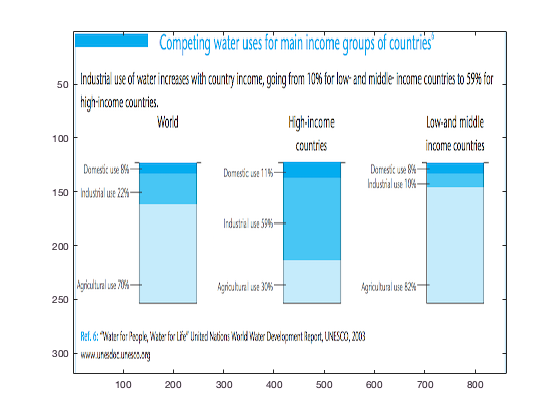

hold on;

## Percentage of Freshwater used in Agriculture

figure(4)
% load excel file to matlab on the percentage of freshwater used in
% agriculture
country1=xlsread('world.data.agriculture.xlsx','a1:a30');
y2007= xlsread('world.data.agriculture.xlsx','b1:b30'); % y2007 is the data for the year 2007
y2012= xlsread('world.data.agriculture.xlsx','c1:c30'); % y2012 is the data for the year 2012
y2014= xlsread('world.data.agriculture.xlsx','d1:d30'); % y2014 is the data for the year 2014
% separating text from number values
[num1, txt1, raw1] = xlsread('world.data.agriculture.xlsx');
labels1=txt1;% seting tick labels as text
bar3(num1); % creating a 3D graph from data set of the 30 countries presented earlier
%labeling of axes
zlabel('Percent of freshwater used for Agriculture')
ylabel Countries
xlabel Years
legend({'Percent Usage 2007','Percent Usage 2012','Percent Usage 2014'},'Location','northwest') % legend to identify color/year correlation
set(gca, 'YTick', 0:29, 'YTickLabel', labels1);% renaming tick labels
set(gca, 'XTick', 1:3, 'XTickLabel', ['2007';'2012';'2014'])% renaming tick labels

# `Percentage of Freshwater used by Agriculture`

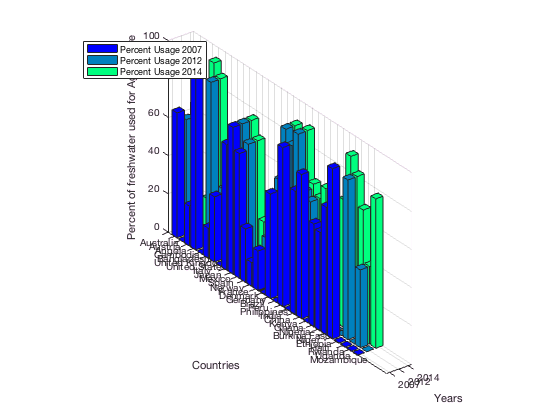

colormap winter

** Questions to ask: Would you like to know the specific values for one of the 30 countries presented?

If yes-- Please type the name of the country you wish to gather more information from:

** For ---country name--- the percent of freshwater use in agriculture was --- in 2007.--- in 2012 and --- in 2014

** if one of the values is 0 for a year instead of value display 'No information available'

## GRACE information on groundwater depletion 

% Figure on groundwater depletion
figure (5)
B= imread('grace.jpg'); %uploads image to matlab
fullscreen=get(0,'ScreenSize'); 
image (B)

# `Worldwide Groundwater Depletion`

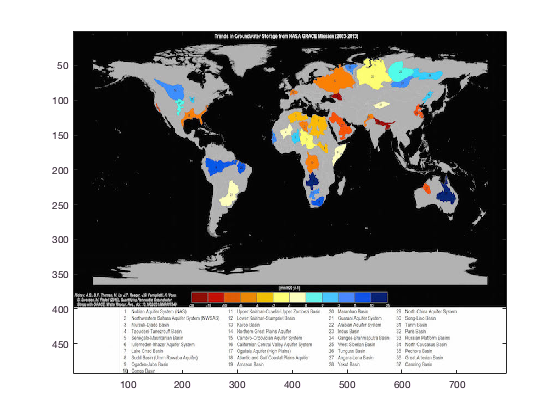

hold on;

# `Water Related Diseases by Country`

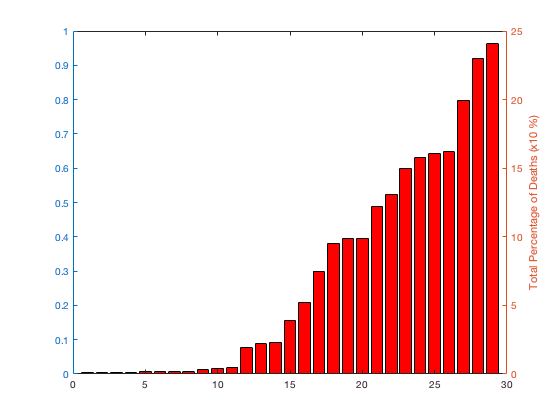

figure(6)
p = xlsread('water_related_diseases_by_country','B5:AD5');

percent = p*100;

x_val = [1:29];

yyaxis right

bar(x_val,percent,'r');

ylabel('Total Percentage of Deaths (x10 %)');

 

water_use = xlsread('Average_Water_Use_Per_Person_Per_Day','B1:B29');

yyaxis left

bar(x_val,water_use,'g','stacked');

Error using bar (line 139)
The length of X must match the number of rows of Y.


ylabel('Water Usage (x100 L)');

 

[~,txt,~] = xlsread('water_related_diseases_by_country','B1:AD1');

txt_label = txt;

xticks(1:29);

set(gca,'xticklabel',txt_label);

title('Water Usage vs. Deaths');

** Another of travis' figures awaiting prompt questions

## User input:

% Conditional Statements- 
contorno=input('Would you like to know any specific information on a country[y/n]?','s');
if (contorno=='y')
prompt='Would you like to know the exact water use per person per day for a specific country?[y/n]';
yesorno=input(prompt,'s');
%Loop to determine what output the user wishes to retrieve from the given
%input: Danny's Code
while(yesorno=='y')
    countryask=input('Enter the country name:','s');
    p=strcmpi(countryask,raw(:,2));
    rowNum=find(p==1);
    fprintf('The average water user per day is of %4.2f liters\n',cell2mat(raw(rowNum,3))); 
    again=input('Would you like to check another country[y/n]?','s');
    if (again=='n')
        break
    end
end   
disp('next question');
end